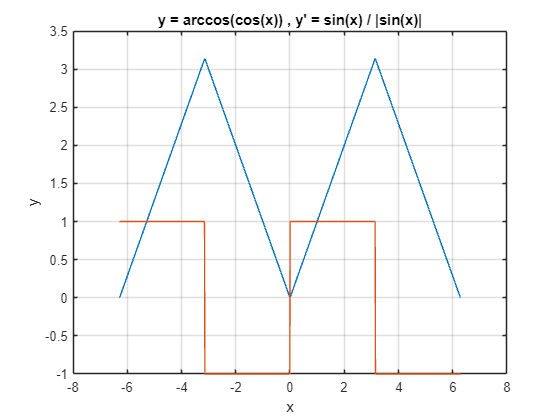

% 3_5_41

% funktionen
fun = @(x) (acos(cos(x)));

% derivatan (simplifierad)
% kan också skrivas som (csc(x)) .* (sqrt((sin(x)).^2))
der = @(x) sin(x) ./ abs(sin(x));

% generera X-värden
x_values = linspace(-2*pi, 2*pi, 1000);

% generera funktionen
y_values = fun(x_values);

% generera derivatan
g_values = der(x_values);

% plotta grafen med både f(x) & f'(x)
plot(x_values,y_values, x_values, g_values);
xlabel('x');
ylabel('y');
title("y = arccos(cos(x)) , y' = sin(x) / |sin(x)|");
grid on;

% Funktionen går inte att derivera när x är en multipel av pi, 
% då sin(±Nπ) där N är ett heltal = 0 vilket blir odefinerat i derivatans funktion.
% I alla andra fall är funktionen kontinuerlig och y' = +1 när x > 0, och
% -1 när x < 0.